clear

addpath('matlab_functions\')

#### Compute Sensitivity

Model = myModel;
freqs = [900 225 100 55]; % (Hz)

for freq = freqs
    tic
    S = ComputeSensitivity(Model, freq);
    fprintf('Compute %g Hz sensitivity took %.2f seconds\n', freq, toc)
    
    element_centers = Model.mesh.elems_center;
    
    fname = sprintf('data/Sensitivity_%dHz_%s.mat', freq, datetime('now','Format','MMdd-HHmm'));
    save(fname, 'S','element_centers')
end

Compute 900 Hz sensitivity took 12.88 seconds
Compute 225 Hz sensitivity took 12.69 seconds
Compute 100 Hz sensitivity took 12.69 seconds
Compute 55 Hz sensitivity took 12.71 seconds



clear feq S elem_centers fname

#### Visualize Sensitivity

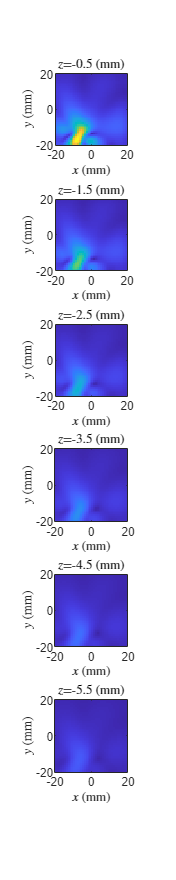

load('data\Sensitivity_100Hz.mat')
VisualizeSensitivity(S, element_centers, 'all')

function S = ComputeSensitivity(Model, freq)

omega = 2*pi * freq;
x = Model.mesh.gauss_points(1,:,:);
y = Model.mesh.gauss_points(2,:,:);
z = Model.mesh.gauss_points(3,:,:);

num_sensors = size(Model.sensors.positions, 2);
num_elems = size(Model.mesh.elems_center, 2);
S = zeros(num_sensors, num_elems);

coilAbovePlate = CoilAbovePlate3D(Model.coil, Model.layers);
[Ex,Ey] = coilAbovePlate.EvaluateField({'Ex' 'Ey'}, x,y,z, omega);
E1 = [Ex;Ey];

for i = 1:num_sensors
    sensor.type = 'MagneticSensor';
    sensor.position = [0 0 Model.sensors.positions(3,i)];
    sensor.axis = Model.sensors.axes(:,i);
    sensorAbovePlate = CoilAbovePlate3D(sensor, Model.layers);

    [Ex,Ey] = sensorAbovePlate.EvaluateField({'Ex' 'Ey'}, ...
        x-Model.sensors.positions(1,i), ...
        y-Model.sensors.positions(2,i), z, omega);
    E2 = [Ex;Ey];
    
    S(i,:) = sum(dot(E1,E2) .* Model.mesh.gauss_weights, 2);    
end

end

function VisualizeSensitivity(S, element_centers, varargin)

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

if isempty(varargin) || strcmpi(varargin{1}, 'all')
    S_norm = vecnorm(S);
else
    S_norm = abs(S(varargin{1},:));
end

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c = reshape(S_norm(mask), sqrt(sum(mask)),[]);

    x = [min(element_centers(1,mask)) max(element_centers(1,mask))] * scale;
    y = [min(element_centers(2,mask)) max(element_centers(2,mask))] * scale;

    subplot(length(z),1,k)
    imagesc(x, y, c.', [0 max(S_norm)])
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end

end